# Compare day1 and day2 behavior

clearvars

% read data
day1_file = 'D:\Ruonan\Projects in the lab\VA_RA_PTB\Analysis Ruonan\Fitpar files\Behavior data fitpar_020519\param_nonparam_day1_021019.txt';
day2_file = 'D:\Ruonan\Projects in the lab\VA_RA_PTB\Analysis Ruonan\Fitpar files\Behavior data fitpar_020519\param_nonparam_day2_021019.txt';
day1_old = readtable(day1_file);
day2_old  =readtable(day2_file);

day1_old.Properties.VariableNames{'Var1'} = 'id';
day2_old.Properties.VariableNames{'Var1'} = 'id';

% read subject grouping
subj_log_file = 'D:\Ruonan\Projects in the lab\VA_RA_PTB\Clinical and behavioral\log_allSubj.xlsx';
log = readtable(subj_log_file);

% join table
day1 = join(day1_old, log, 'Keys', 'id');
day2 = join(day2_old, log, 'Keys', 'id');

% calculate model free attitude
day1.G_risk = mean([day1.G_risk25, day1.G_risk50, day1.G_risk75], 2);
day1.G_amb = mean([day1.G_amb24, day1.G_amb50, day1.G_amb74], 2);
day1.G_amb_risk50 = day1.G_amb - day1.G_risk50;
day1.L_risk = mean([day1.L_risk25, day1.L_risk50, day1.L_risk75], 2);
day1.L_amb = mean([day1.L_amb24, day1.L_amb50, day1.L_amb74], 2);
day1.L_amb_risk50 = day1.L_amb - day1.L_risk50;

day2.G_risk = mean([day2.G_risk25, day2.G_risk50, day2.G_risk75], 2);
day2.G_amb = mean([day2.G_amb24, day2.G_amb50, day2.G_amb74], 2);
day2.G_amb_risk50 = day2.G_amb - day2.G_risk50;
day2.L_risk = mean([day2.L_risk25, day2.L_risk50, day2.L_risk75], 2);
day2.L_amb = mean([day2.L_amb24, day2.L_amb50, day2.L_amb74], 2);
day2.L_amb_risk50 = day2.L_amb - day2.L_risk50;

% group inclusion

day1.control_idx = day1.isExcluded_behavior == 0 & strcmp(day1.group, 'C');
% sum(day1.control_idx)
day1.ptsd_idx = day1.isExcluded_behavior == 0 & strcmp(day1.group, 'P');
% sum(day1.ptsd_idx)
day1.remit_idx = day1.isExcluded_behavior == 0 & strcmp(day1.group, 'R');
% sum(day1.remit_idx)

day2.control_idx = day2.isExcluded_behavior == 0 & strcmp(day2.group, 'C');
% sum(day2.control_idx)
day2.ptsd_idx = day2.isExcluded_behavior == 0 & strcmp(day2.group, 'P');
% sum(day2.ptsd_idx)
day2.remit_idx = day2.isExcluded_behavior == 0 & strcmp(day2.group, 'R');
% sum(day2.remit_idx)

# Risk gain, constrained

### All subjects

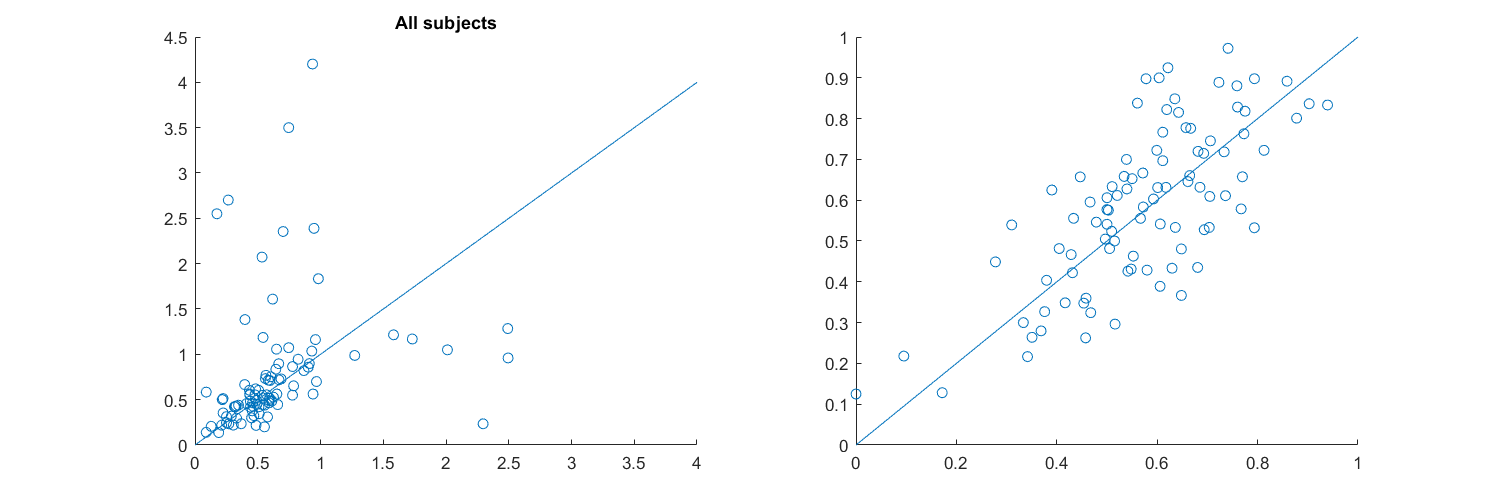

% risk attitude, constrained, gain, all subjects
figure('Position', [0,0,1200,400])
subplot(1,2,1)
scatter(day1.alpha_2, day2.alpha_2)
title('All subjects')
x = linspace(0,4);
y = x;
line(x,y)


subplot(1,2,2)
scatter(day1.G_risk, day2.G_risk)
x = linspace(0,1);
y = x;
line(x,y)

% t test comparing post and pre
[h,p,ci,stats] = ttest(day1.alpha_2, day2.alpha_2)

h = 0

p = 0.0638

ci =    -0.2914
    0.0083


stats = struct with fields:
    tstat: -1.8761
       df: 93
       sd: 0.7314


[h,p,ci,stats] = ttest(day1.G_risk, day2.G_risk)

h = 0

p = 0.3129

ci =    -0.0424
    0.0137


stats = struct with fields:
    tstat: -1.0148
       df: 93
       sd: 0.1371


### Groups

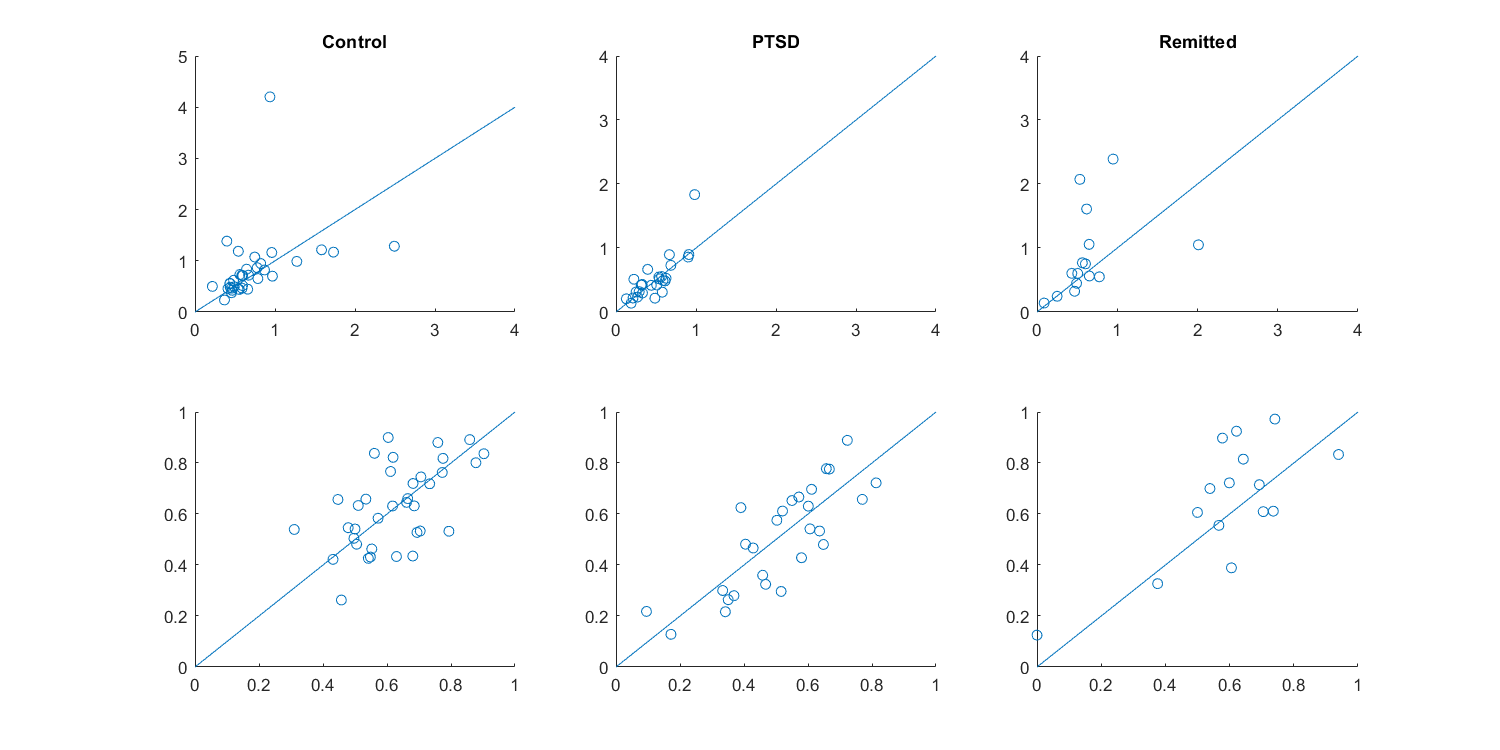

% risk attitude, constrained, gain, three groups of subjects
figure('Position', [0,0,1200,600])

% Control
subplot(2,3,1)
scatter(day1.alpha_2(day1.control_idx), day2.alpha_2(day2.control_idx))
title('Control')
x = linspace(0,4);
y = x;
line(x,y)


subplot(2,3,4)
scatter(day1.G_risk(day1.control_idx), day2.G_risk(day2.control_idx))
x = linspace(0,1);
y = x;
line(x,y)

% PTSD
subplot(2,3,2)
scatter(day1.alpha_2(day1.ptsd_idx), day2.alpha_2(day2.ptsd_idx))
title('PTSD')
x = linspace(0,4);
y = x;
line(x,y)


subplot(2,3,5)
scatter(day1.G_risk(day1.ptsd_idx), day2.G_risk(day2.ptsd_idx))
x = linspace(0,1);
y = x;
line(x,y)

% remitted
subplot(2,3,3)
scatter(day1.alpha_2(day1.remit_idx), day2.alpha_2(day2.remit_idx))
title('Remitted')
x = linspace(0,4);
y = x;
line(x,y)


subplot(2,3,6)
scatter(day1.G_risk(day1.remit_idx), day2.G_risk(day2.remit_idx))
x = linspace(0,1);
y = x;
line(x,y)

% t test
[h,p,ci,stats] = ttest(day1.alpha_2(day1.control_idx), day2.alpha_2(day2.control_idx))
[h,p,ci,stats] = ttest(day1.G_risk(day1.control_idx), day2.G_risk(day2.control_idx))

[h,p,ci,stats] = ttest(day1.alpha_2(day1.ptsd_idx), day2.alpha_2(day2.ptsd_idx))
[h,p,ci,stats] = ttest(day1.G_risk(day1.ptsd_idx), day2.G_risk(day2.ptsd_idx))

[h,p,ci,stats] = ttest(day1.alpha_2(day1.remit_idx), day2.alpha_2(day2.remit_idx))
[h,p,ci,stats] = ttest(day1.G_risk(day1.remit_idx), day2.G_risk(day2.remit_idx))

# Ambiguous gain, constrained

### All subjects

% ambig attitude, constrained, gain
figure('Position', [0,0,1200,400])
subplot(1,2,1)
scatter(day1.beta_2, day2.beta_2)
title('All subjects')
x = linspace(-4,4);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.G_amb_risk50, day2.G_amb_risk50)
x = linspace(-1, 1);
y = x;
line(x,y)

% t test
[h, p, ci, stats] = ttest(day1.beta_2, day2.beta_2)
[h, p, ci, stats] = ttest(day1.G_amb_risk50, day2.G_amb_risk50)

### Groups

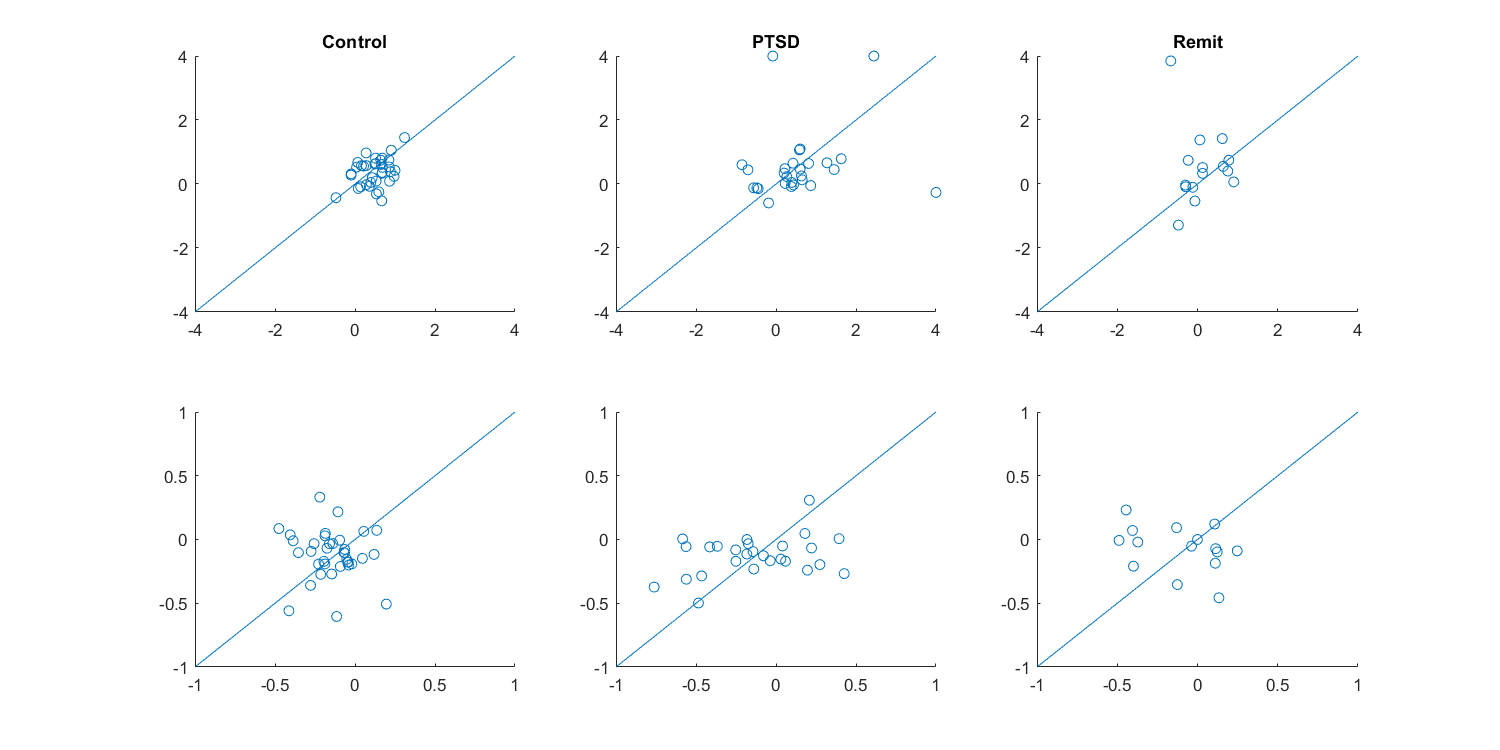

figure('Position', [0,0,1200,600])

% ptsd
subplot(2,3,1)
scatter(day1.beta_2(day1.control_idx), day2.beta_2(day2.control_idx))
title('Control')
x = linspace(-4,4);
y = x;
line(x,y)

subplot(2,3,4)
scatter(day1.G_amb_risk50(day1.control_idx), day2.G_amb_risk50(day2.control_idx))
x = linspace(-1, 1);
y = x;
line(x,y)

% ptsd
subplot(2,3,2)
scatter(day1.beta_2(day1.ptsd_idx), day2.beta_2(day2.ptsd_idx))
title('PTSD')
x = linspace(-4,4);
y = x;
line(x,y)

subplot(2,3,5)
scatter(day1.G_amb_risk50(day1.ptsd_idx), day2.G_amb_risk50(day2.ptsd_idx))
x = linspace(-1, 1);
y = x;
line(x,y)

% remit
subplot(2,3,3)
scatter(day1.beta_2(day1.remit_idx), day2.beta_2(day2.remit_idx))
title('Remit')
x = linspace(-4,4);
y = x;
line(x,y)

subplot(2,3,6)
scatter(day1.G_amb_risk50(day1.remit_idx), day2.G_amb_risk50(day2.remit_idx))
x = linspace(-1, 1);
y = x;
line(x,y)

% t test
[h, p, ci, stats] = ttest(day1.beta_2(day1.control_idx), day2.beta_2(day2.control_idx))

h = 0

p = 0.1377

ci =    -0.0386
    0.2681


stats = struct with fields:
    tstat: 1.5192
       df: 35
       sd: 0.4532


[h, p, ci, stats] = ttest(day1.G_amb_risk50(day1.control_idx), day2.G_amb_risk50(day2.control_idx))

h = 0

p = 0.5863

ci =    -0.1110
    0.0637


stats = struct with fields:
    tstat: -0.5492
       df: 35
       sd: 0.2582



[h, p, ci, stats] = ttest(day1.beta_2(day1.ptsd_idx), day2.beta_2(day2.ptsd_idx))

h = 0

p = 0.9857

ci =    -0.5298
    0.5206


stats = struct with fields:
    tstat: -0.0181
       df: 26
       sd: 1.3276


[h, p, ci, stats] = ttest(day1.G_amb_risk50(day1.ptsd_idx), day2.G_amb_risk50(day2.ptsd_idx))

h = 0

p = 0.9178

ci =    -0.1275
    0.1152


stats = struct with fields:
    tstat: -0.1043
       df: 26
       sd: 0.3067



[h, p, ci, stats] = ttest(day1.beta_2(day1.remit_idx), day2.beta_2(day2.remit_idx))

h = 0

p = 0.2420

ci =    -1.1196
    0.3070


stats = struct with fields:
    tstat: -1.2216
       df: 14
       sd: 1.2881


[h, p, ci, stats] = ttest(day1.G_amb_risk50(day1.remit_idx), day2.G_amb_risk50(day2.remit_idx))

h = 0

p = 0.7028

ci =    -0.2340
    0.1621


stats = struct with fields:
    tstat: -0.3895
       df: 14
       sd: 0.3577


# Risk loss, constrained

## All subjects

% risk attitude, constrained, loss
figure('Position', [0,0,1200,400])

subplot(1,2,1)
scatter(day1.alpha_3, day2.alpha_3)
x = linspace(0,4);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.L_risk, day2.L_risk)
x = linspace(0,1);
y = x;
line(x, y)

% t test
[h, p, c, stats] = ttest(day1.alpha_3, day2.alpha_3)
[h, p, c, stats] = ttest(day1.L_risk, day2.L_risk)

## Groups

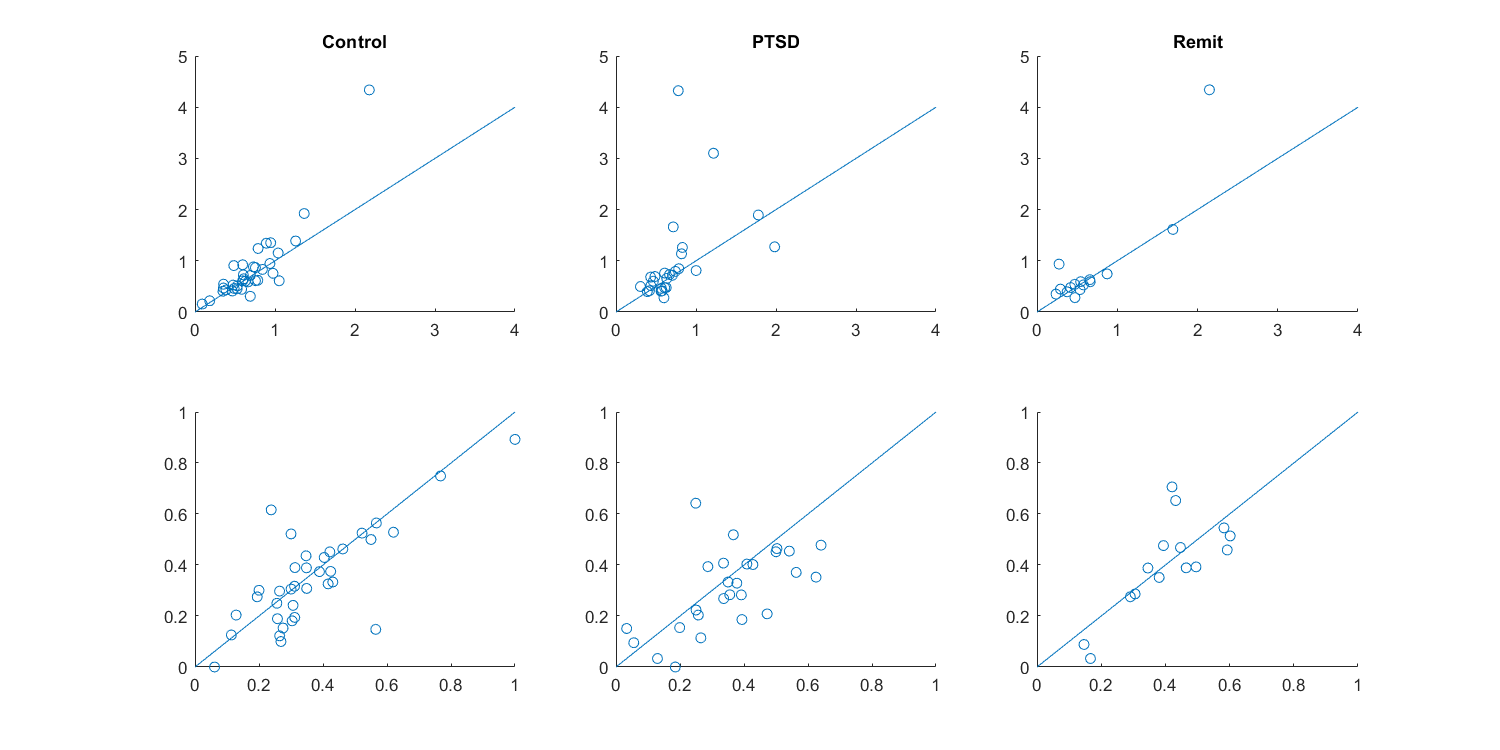

figure('Position', [0,0,1200,600])

% control
subplot(2,3,1)
scatter(day1.alpha_3(day1.control_idx), day2.alpha_3(day2.control_idx))
title('Control')
x = linspace(0,4);
y = x;
line(x,y)

subplot(2,3,4)
scatter(day1.L_risk(day1.control_idx), day2.L_risk(day2.control_idx))
x = linspace(0,1);
y = x;
line(x, y)

% ptsd
subplot(2,3,2)
scatter(day1.alpha_3(day1.ptsd_idx), day2.alpha_3(day2.ptsd_idx))
title('PTSD')
x = linspace(0,4);
y = x;
line(x,y)

subplot(2,3,5)
scatter(day1.L_risk(day1.ptsd_idx), day2.L_risk(day2.ptsd_idx))
x = linspace(0,1);
y = x;
line(x, y)

% Remit
subplot(2,3,3)
scatter(day1.alpha_3(day1.remit_idx), day2.alpha_3(day2.remit_idx))
title('Remit')
x = linspace(0,4);
y = x;
line(x,y)

subplot(2,3,6)
scatter(day1.L_risk(day1.remit_idx), day2.L_risk(day2.remit_idx))
x = linspace(0,1);
y = x;
line(x, y)

% t test
[h, p, c, stats] = ttest(day1.alpha_3(day1.control_idx), day2.alpha_3(day2.control_idx))
[h, p, c, stats] = ttest(day1.L_risk(day1.control_idx), day2.L_risk(day2.control_idx))

[h, p, c, stats] = ttest(day1.alpha_3(day1.ptsd_idx), day2.alpha_3(day2.ptsd_idx))
[h, p, c, stats] = ttest(day1.L_risk(day1.ptsd_idx), day2.L_risk(day2.ptsd_idx))

[h, p, c, stats] = ttest(day1.alpha_3(day1.remit_idx), day2.alpha_3(day2.remit_idx))
[h, p, c, stats] = ttest(day1.L_risk(day1.remit_idx), day2.L_risk(day2.remit_idx))

# Ambiguous Loss, constrained

## All subjects

% ambig attitude, constrained, loss
figure('Position', [0,0,1200,400])

subplot(1,2,1)
scatter(day1.beta_3, day2.beta_3)
title('All subjects')
x = linspace(-4,2.5);
y = x;
line(x,y)

subplot(1,2,2)
scatter(day1.L_amb_risk50, day2.L_amb_risk50)
x = linspace(-0.8, 0.4);
y = x;
line(x, y)

% t test
[h, p, ci, stats] = ttest(day1.beta_3, day2.beta_3)
[h, p, ci, stats] = ttest(day1.L_amb_risk50, day2.L_amb_risk50)

## Groups

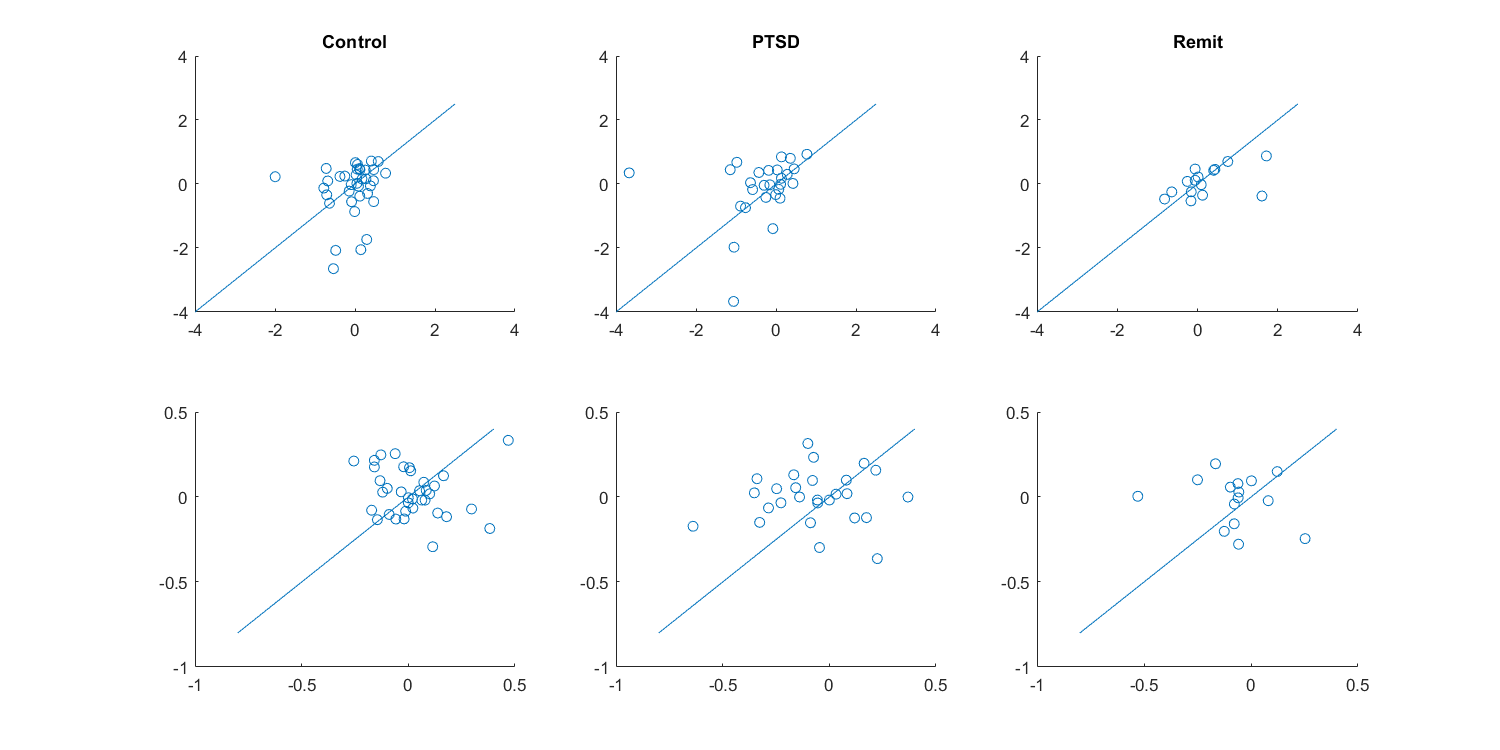

figure('Position', [0,0,1200,600])

% control
subplot(2,3,1)
scatter(day1.beta_3(day1.control_idx), day2.beta_3(day2.control_idx))
title('Control')
x = linspace(-4,2.5);
y = x;
line(x,y)

subplot(2,3,4)
scatter(day1.L_amb_risk50(day1.control_idx), day2.L_amb_risk50(day2.control_idx))
x = linspace(-0.8, 0.4);
y = x;
line(x, y)

% PTSD
subplot(2,3,2)
scatter(day1.beta_3(day1.ptsd_idx), day2.beta_3(day2.ptsd_idx))
title('PTSD')
x = linspace(-4,2.5);
y = x;
line(x,y)

subplot(2,3,5)
scatter(day1.L_amb_risk50(day1.ptsd_idx), day2.L_amb_risk50(day2.ptsd_idx))
x = linspace(-0.8, 0.4);
y = x;
line(x, y)

% remit
subplot(2,3,3)
scatter(day1.beta_3(day1.remit_idx), day2.beta_3(day2.remit_idx))
title('Remit')
x = linspace(-4,2.5);
y = x;
line(x,y)

subplot(2,3,6)
scatter(day1.L_amb_risk50(day1.remit_idx), day2.L_amb_risk50(day2.remit_idx))
x = linspace(-0.8, 0.4);
y = x;
line(x, y)

% t test
% control
[h, p, ci, stats] = ttest(day1.beta_3(day1.control_idx), day2.beta_3(day2.control_idx))
[h, p, ci, stats] = ttest(day1.L_amb_risk50(day1.control_idx), day2.L_amb_risk50(day2.control_idx))

% PTSD
[h, p, ci, stats] = ttest(day1.beta_3(day1.ptsd_idx), day2.beta_3(day2.ptsd_idx))
[h, p, ci, stats] = ttest(day1.L_amb_risk50(day1.ptsd_idx), day2.L_amb_risk50(day2.ptsd_idx))

% PTSD
[h, p, ci, stats] = ttest(day1.beta_3(day1.remit_idx), day2.beta_3(day2.remit_idx))
[h, p, ci, stats] = ttest(day1.L_amb_risk50(day1.remit_idx), day2.L_amb_risk50(day2.remit_idx))
